# MPC control with CasADi & CarSim

## read the path

first we need to read the path of the car

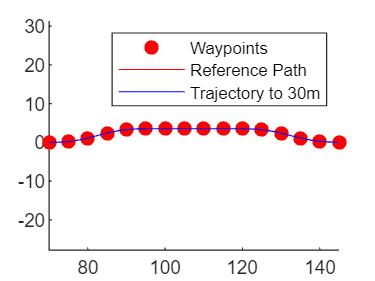

path_table = readtable('maps.csv');
path = path_table{:,:};

waypoints = path;
refPath = referencePathFrenet(waypoints);
connector = trajectoryGeneratorFrenet(refPath);
initState = [0 0 0 0 0 0];  % [S ds ddS L dL ddL]
termState = [140 0 0 0 0 0]; % [S ds ddS L dL ddL]
[~,trajGlobal] = connect(connector,initState,termState,5);
show(refPath);
hold on
axis equal
plot(trajGlobal.Trajectory(:,1),trajGlobal.Trajectory(:,2),'b')
legend(["Waypoints","Reference Path","Trajectory to 30m"])


ref_path = [trajGlobal.Trajectory(:,1) trajGlobal.Trajectory(:,2)]

ref_path =    70.0000         0
   70.0109    0.0001
   70.0843    0.0008
   70.2758    0.0026
   70.6335    0.0063
   71.1983    0.0134
   72.0044    0.0288
   73.0792    0.0647
   74.4427    0.1490
   76.1050    0.3339


current_point = [100 2];
closest_point = dsearchn(ref_path,current_point)

closest_point = 18

## figure out the lateral control params

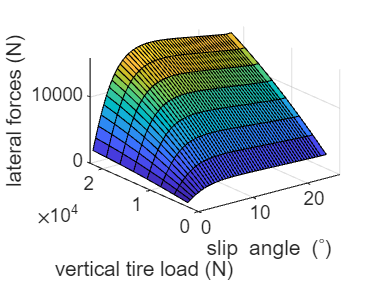

% physical params
g = 9.8;

% vehicle params
weight = 1807.2; % kg
wheelbase = 2950*10^-3; % mm->m
R_tire = 402*10^-3; % mm->m
beta_1 = 3.538;
beta_2 = 2.06;
beta_3 = 1.404;
beta_4 = 1;
beta_5 = 0.713;
beta_6 = 0.582;
beta_dif = 4.1;

% engine params
speed_max = 6200; % rpm
speed_min = 725; % rpm
omega_max = speed_max*0.1047198; % rpm->rad/s
omega_min = speed_min*0.1047198; % rpm->rad/s, idle

yita_d = 1; % differencial efficiency
yita_g = 1; % gear box efficiency

% resistance params
%%%%%%%%%%%%%%%%%%%%% it hasn't been done yet%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu_R = 0.02;
gradient_degree = 59.7;
gradient = deg2rad(gradient_degree);
rho = 1.29;
c_d = 0.3; % drag coefficient

% simulation params
dt = 0.01; % s
a = 1180*10^-3; % mm->m
b = wheelbase-a;
m1 = 1590; % kg sprung mass
m_f = 102.2; % kg
m_r = 115; % kg
Izz = 2687.1; % kg-m^2 yaw inertia

% the params below is used to linearlize the model
slip_angle_min = 0; % degree
slip_angle_max = 4; % degree

slip_angle_table = readtable('lateral_force_slip_angle.csv');
slip_angle_degrees = slip_angle_table{2:end, 1}';
vertical_tire_loads = slip_angle_table{1,2:end};
lateral_forces = slip_angle_table{2:end,2:end};

% plot the data from carsim
[x,y] = meshgrid(slip_angle_degrees,vertical_tire_loads);
z = lateral_forces';
figure('Color','w');
surf(x,y,z);
xlabel('slip angle (^{\circ})');
ylabel('vertical tire load (N)');
zlabel('lateral forces (N)');
hold off;

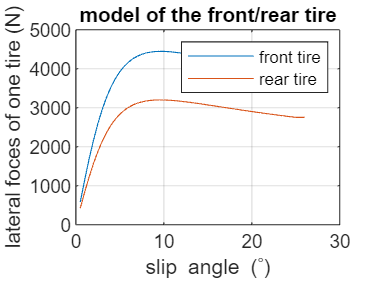



% calculate the vertical load of each tire
front_tire_vertical_load = 0.5*(m1/(a+b)*b + m_f)*g;
rear_tire_vertical_load = 0.5*(m1/(a+b)*a + m_r)*g;

[xx, yy] = meshgrid(slip_angle_degrees,[front_tire_vertical_load,rear_tire_vertical_load]);
% use insert point method
zz = interp2(x,y,z,xx,yy,'spline');
f_vertical_front = zz(1,:);
f_vertical_rear = zz(2,:); 

% plot
figure('Color','w');
plot(slip_angle_degrees,f_vertical_front);
hold on;
grid on;
title("model of the front/rear tire");
plot(slip_angle_degrees,f_vertical_rear);
legend('front tire', 'rear tire');
xlabel('slip angle (^{\circ})');
ylabel('lateral foces of one tire (N)');
hold off;

## calculate the stiffness

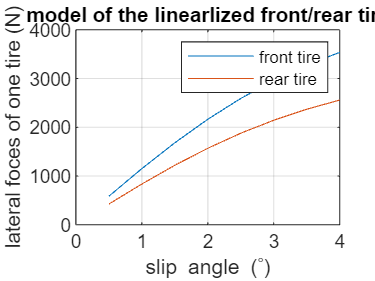

linear_slip_angle = slip_angle_degrees(slip_angle_degrees>=0 & slip_angle_degrees<=4);
linear_vertical_front = f_vertical_front(slip_angle_degrees>=0 & slip_angle_degrees<=4);
linear_vertical_rear = f_vertical_rear(slip_angle_degrees>=0 & slip_angle_degrees<=4);

% plot the reranged part to be linearlized
% plot
figure('Color','w');
plot(linear_slip_angle,linear_vertical_front);
hold on;
grid on;
title("model of the linearlized front/rear tire");
plot(linear_slip_angle,linear_vertical_rear);
legend('front tire', 'rear tire');
xlabel('slip angle (^{\circ})');
ylabel('lateral foces of one tire (N)');
xlim([0 4])
hold off;


% calculate the slope
fun = @(params, x) params(1) * x; % y = kx
initialParams = 800;

% use least squares method to calculate the slope
params_front = lsqcurvefit(fun, initialParams, linear_slip_angle, linear_vertical_front);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C_af = -2*params_front(1)*180/pi % rad->degree

C_af = -1.1073e+05


params_rear = lsqcurvefit(fun, initialParams, linear_slip_angle, linear_vertical_rear);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


C_ar = -2*params_rear(1)*180/pi

C_ar = -8.0188e+04

## calculate matrix

v = 50/3.6; % the velocity of the car km/hr -> m/s

% construct the state space
A = [0,v,1,0;
    0,0,0,1;
    0,0,(C_af+C_ar)/weight/v,(a*C_af-b*C_ar)/weight/v-v;
    0,0,(a*C_af-b*C_ar)/Izz/v,(a^2*C_af+b^2*C_ar)/Izz/v];

B = [0;0;-C_af/weight;-a*C_ar/Izz];

Q = eye(4);
R = 0.1;
k = lqr(A,B,Q,R);